format shortg
clear all

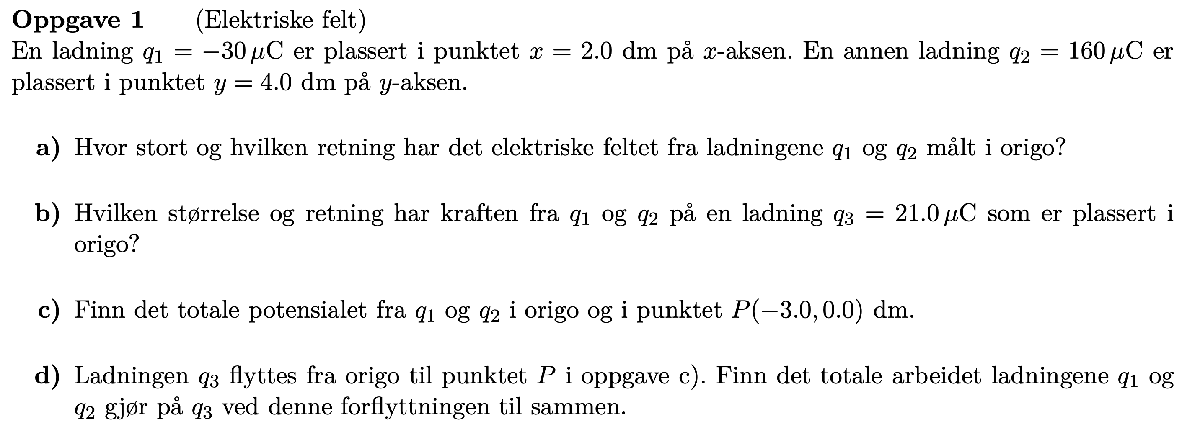

q1 = -30 * 10^-6;
x1 = 2 * 10^-1;
q2 = 160 * 10^-6;
y2 = 4 * 10^-1;

a)

E1 = ElektriskFeltstyrkeFraPunktladning(0, q1, x1);
E2 = ElektriskFeltstyrkeFraPunktladning(0, q2, y2);
E = sqrt(E1^2+E2^2); % nedover mot høyre
signif(E, 3)

ans =     11200000


b)

q3 = 21 * 10^-6;
F = E * q3;
signif(F, 2)

ans =    240


c)

x_3 = -3*10^-1;
U_origo = PotensialFraPunktladning(0, q1, x1) + PotensialFraPunktladning(0, q2, y2);
signif(U_origo, 2)

ans =      2200000


U_3 = PotensialFraPunktladning(0, q1, x1-x_3) + PotensialFraPunktladning(0, q2, sqrt(y2^2+x_3^2));
signif(U_3, 2)

ans =      2300000


d)

PotensiellEnergi_origo = U_origo * q3;
PotensiellEnergi_3 = U_3 * q3;
W = -(PotensiellEnergi_3 - PotensiellEnergi_origo);
signif(W, 2)

ans =          -1.9


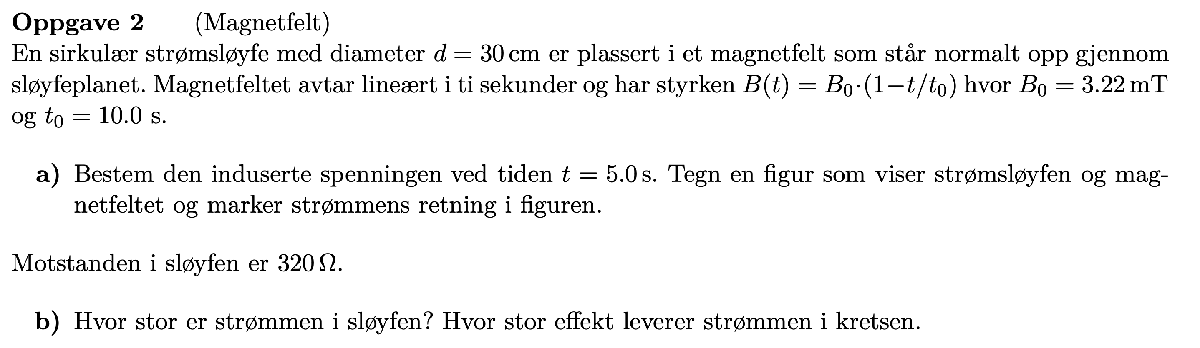

d = 30 * 10^-2;
B_0 = 3.22 * 10^-3;
t_0 = 10;
B = @(t)B_0 * (1-t/t_0);

a)


$$\varepsilon =\frac{d\Phi_B }{\textrm{dt}}=\frac{A*B}{\textrm{dt}}=A*\frac{B}{\textrm{dt}}$$



$$B^{\prime } \left(t\right)=-\frac{B_0 }{t_0 }$$


B_dt = -(B_0/t_0);
B_t5 = B(5);
V = ArealSirkel(d/2) * abs(B_dt);
signif(V, 2)

ans =       2.3e-05


Strømmen vil gå mot klokken på grunn av Lenz-lov om at strømmen motvirker endringen i magnetfeltet.

b)

R = 320;
I = ohms_lov(V, R, 0);
signif(I, 2)

ans =       7.1e-08


P = ElektriskEffekt(0, 0, I, R);
signif(P, 2)

ans =       1.6e-12


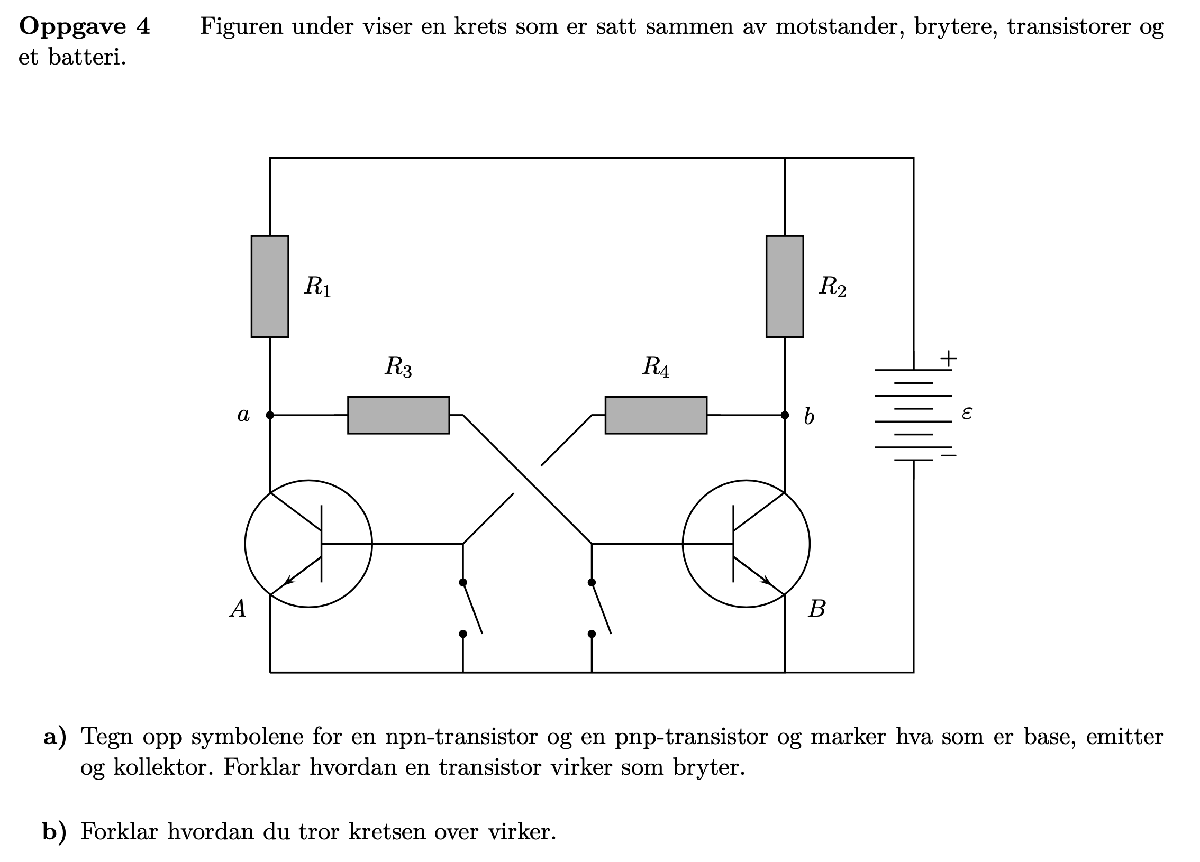

a)

En transistor virker som en bryter ved at det kun går strøm gjennom transistoren dersom det går strøm til basen som gir den en base-emitter spenning over terskelen (vanligvis 0.6 Volt - 0.7 Volt).					

Om base-emitterspenningen er lik 0 så vil det ikke gå strøm fra base til emitter. Da vil transistoren være en isolator (det er en åpen bryter). Det vil ikke gå strøm fra kollektor til basen. 				

Om det er spenning over base-emitter vil det gå strøm fra base til emitter og derfor også fra kollektor til emitter (det er en lukket bryter). 

b)					

Om det går strøm igjennom transistor A, vil ikke spenningen på A’s kollektor være stor nok til at det går strøm i basen på transistor B. Det vil derfor ikke gå kolektor-emitterstrøm i transistor B. 				

Om nå venstre bryter lukkes en kort tid vil det slutte å gå base-emitter-strøm i transistor A. Om motstan- dene R1 og R3 er valg med omhu vil det gå tilstrekkelig med base-emitter-strøm i transistor B slik at B er åpen. Av samme grunn som over vil A være lukket. 					

Om bryteren til høyre lukkes en kort tid vil det slutte å gå strøm i transistor B og A vil være åpen. Kretsen husker med andre ord hvilken av de to bryteren som var åpen sist. Dette er en minne krets. 

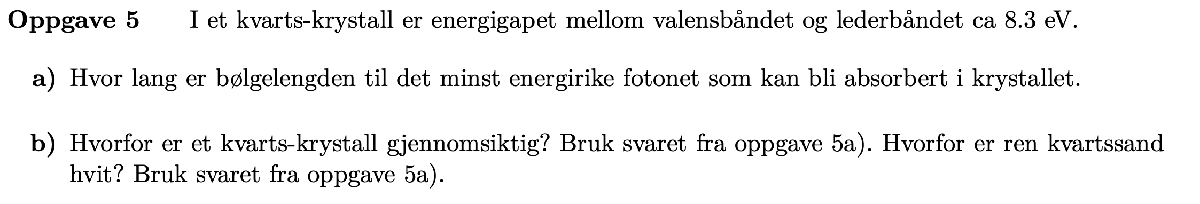

a)

fotonets energi: $E=h\;f$

fotonets bølgelengde: $\lambda =\frac{\textrm{hc}}{E}$

de broglies bølgeformel $m*v=\frac{h}{\lambda }$

E = 8.3; %eV
bolgelengden = h_eVs * c/E;
signif(bolgelengden, 2)

ans =       1.5e-07


Vi ser at det minst energiriket fotonet er på $150\;\textrm{nm}$

b)

Synlig lys er fra $380\textrm{nm}$ til $750\textrm{nm}$ dette betyr at kvartskrystall kun kan ta opp fotoner med en bolgelengde med svært høyere energi enn det synlige lys, som igjen betyr at synlig lys som treffer en ren krystall vil gå ett igjennom uten å bli absorbert.

Ren kvartssand er hvit ettersom de teknisk sett er gjennomsiktig, men sandkornene er ikke perfekte krystalkler så de vil sende lyset ut i mange forskjellige retninger, jgør dette med masse sandkorn og resultatet er masse synlig lys i alle bølgelengder som blir reflektert rundt, dette resulterer i det vi observerer som hvitt.